clear; clc; clf; close all

## Igniter sizing for Methanol-Nitrous Oxide Igniter

This is a prelimary document that will be sporadically updated as more analysis is required for igniter sizing.

Mass Flow Rate: 0.03kg/s Mass flow rate will be 1-2% of engine's, whose mass flow rate is about 1.5kg/s.

Oxidizer Density: 800kg/m3 Density of Nitrous Oxide. Using this graph, I'm assuming a temperature of 20 degrees, so the density will be 800 kg/m3.

Fuel Density: 792kg/m3 Density of Methanol, which according to google is 792 kg/m3.

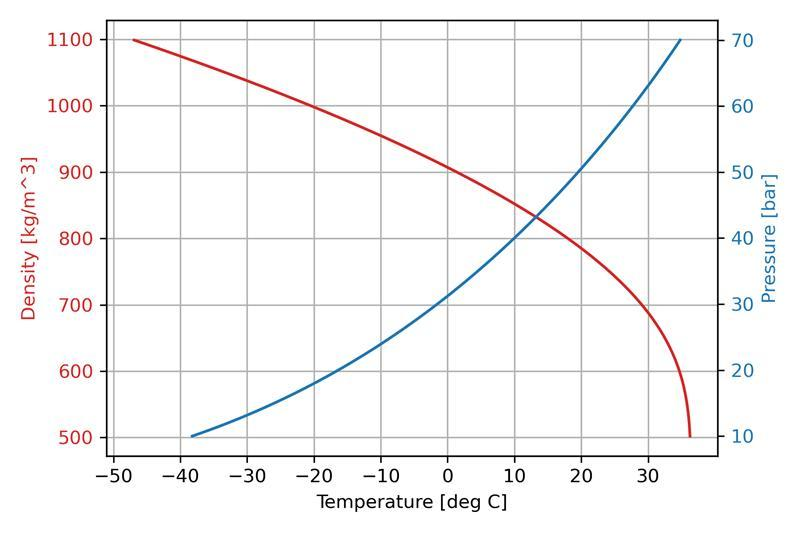

Figure 1: Density and Pressure against Temperature of Nitrous Oxide

O/F: 3.5 Oxidizer mass / Fuel mass. Same as THANOS.

#### **Pressures**

Tank/Injector Pressure: 30 bar. According to figure 2, it will be safe to assume a tank pressure of at least 30 bars, this will be used as the pressure before the injectors.

Chamber Pressure 25 bar. According to figure 2, chamber pressure never reaches above 20 bars. As a safety margin, the injector

**Chamber Presure A**

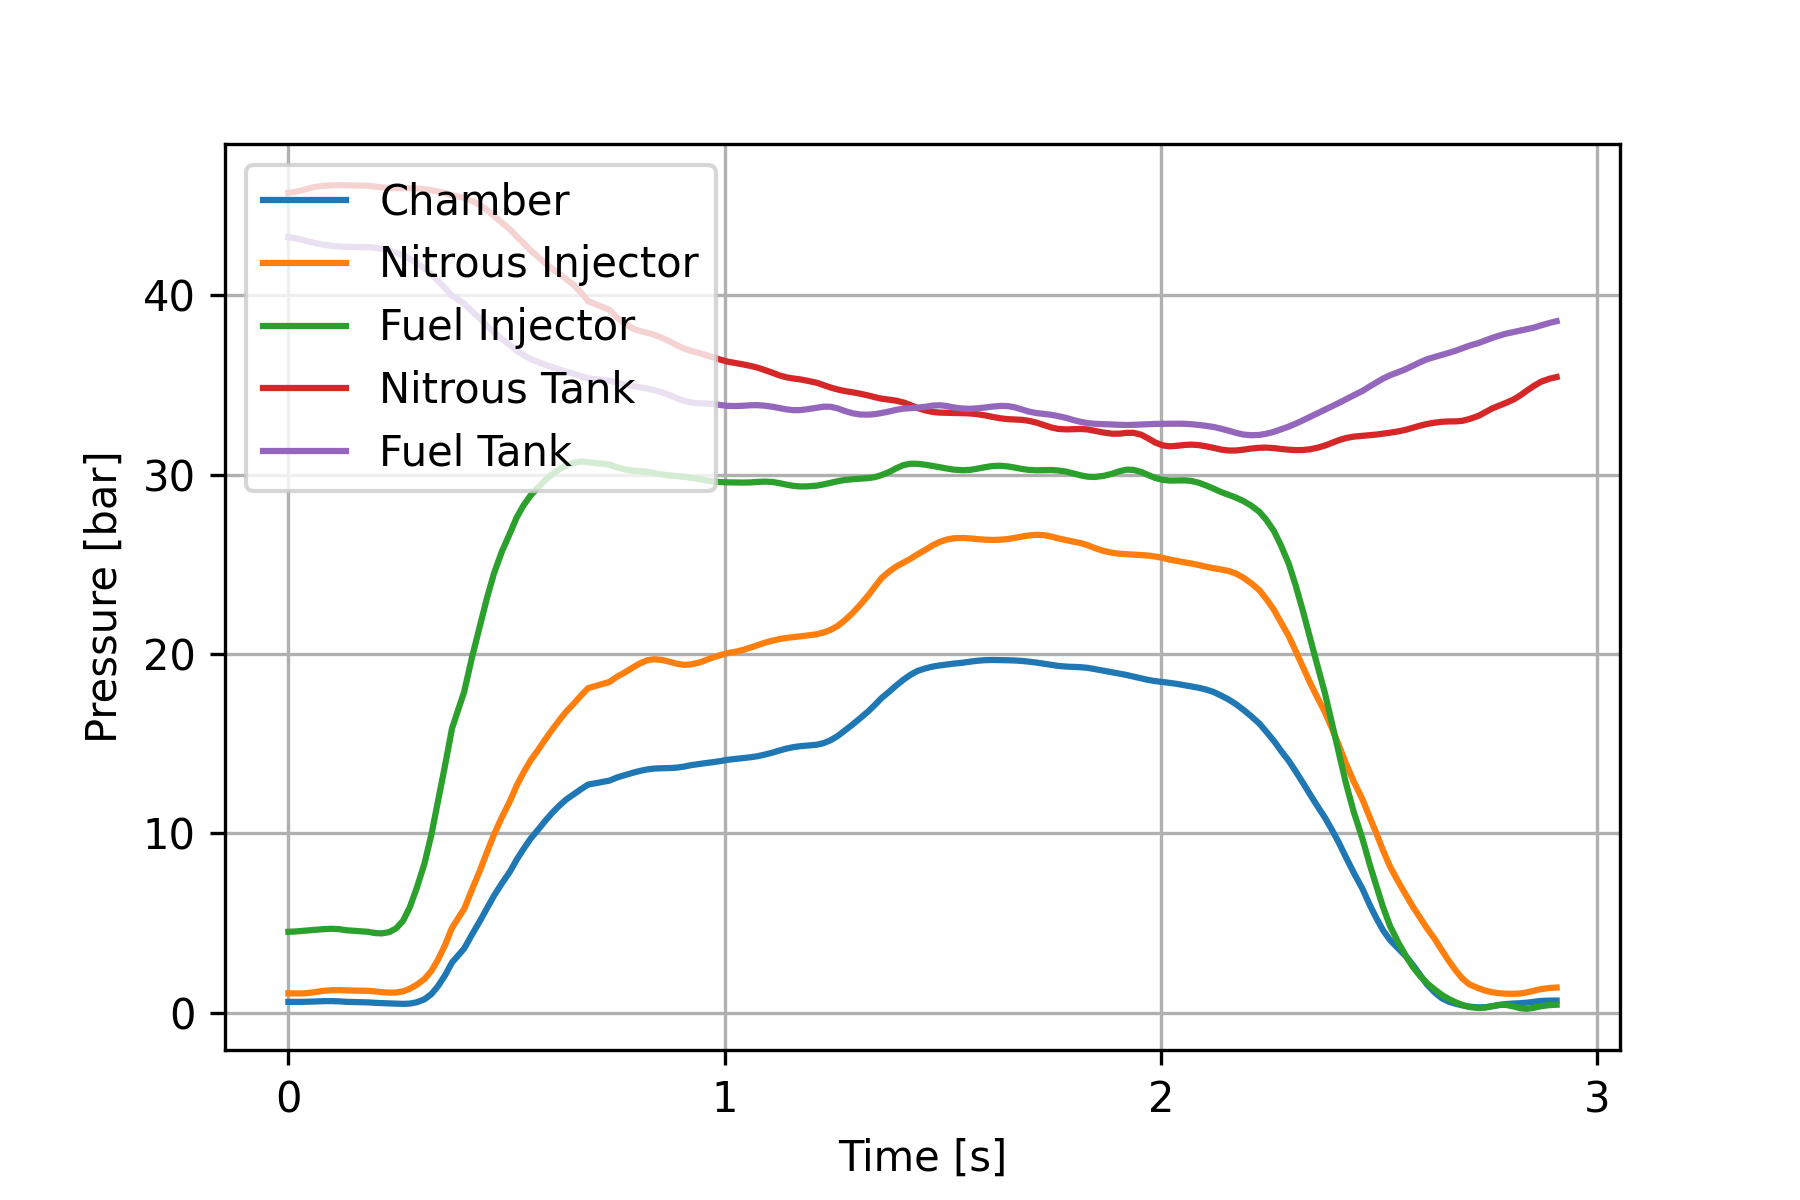

Figure 2: THANOS Hot fire pressure transducer data

mdot = 0.0016;
d_o = 800;
d_f = 792;
p_i = 30e5;
p_c = 25e5;
OF = 3.5;
mdot_o = mdot * OF / (OF + 1);
mdot_f = mdot / (OF + 1);

The discharge coefficient will be used to calculate the injector area required.


$$C_d =\frac{\dot{m} }{\rho \dot{V} }=\frac{\dot{m} }{\rho \textrm{Au}}$$


Assuming negligable piping velocities, Bernoulli's principle can be used to estimate the pressure drop given velocity.


$$P=P_0 +\frac{1}{2}\rho u^2$$


Assuming initially static,


$$P-P_0 =\Delta P=\frac{1}{2}\rho u^2$$


Which can be rearranged to


$$u=\sqrt{\frac{2\Delta P}{\rho }}$$


Thus,


$$C_d =\frac{\dot{m} }{\rho A\sqrt{\frac{2\Delta P}{\rho }}}$$


Rearranged to solve for A,


$$A=\frac{\dot{m} }{C_d \sqrt{2\rho \Delta P}}$$


$C_d$ for an average hole is 0.5-0.7. I'm estimating 0.7 according to this table:

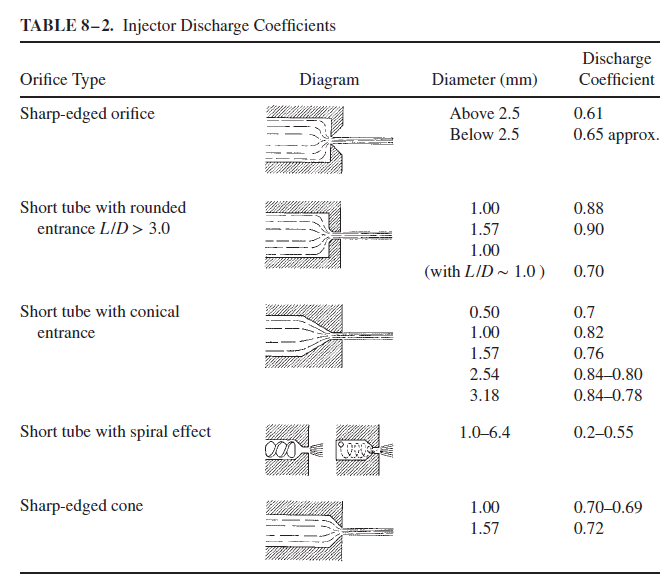

C_d = 0.7;
p_d = p_i - p_c;
A_o = mdot_o / C_d / sqrt(2 * d_o * p_d);
A_f = mdot_f / C_d / sqrt(2 * d_o * p_d);
D_o = sqrt(4 * A_o / pi);
D_f = sqrt(4 * A_f / pi);
stringD_o= sprintf("Oxidizer Injector Diameter: %.3gmm \n", D_o * 1000);
stringD_f = sprintf("Fuel Injector Diameter: %.3gmm", D_f * 1000);
disp(strcat(stringD_o,stringD_f));

Oxidizer Injector Diameter: 0.283mm 
Fuel Injector Diameter: 0.151mm


Gamma 1.1394 From CEA

Molecular Weight 26.653 From CEA

Temperature Combustion 3090.44

Temperature Throat 2920.48

Pressure Throat 17.302

gamma = 1.1394;
mr = 26.619;
t_c = 3075.23;
t_t = 2907.90;
p_t = 14.424e5;
M_e = 2.616;

R = 8314.46 / mr;

A_t = mdot/p_t * sqrt(R * t_t / gamma);
A_e = A_t / M_e * ((1 + (gamma - 1)/2 * M_e^2)/(1/2 * (gamma + 1)))^((gamma + 1)/(2 * (gamma - 1)));
D_t = sqrt(4 * A_t / pi);
D_e = sqrt(4 * A_e / pi);

expansion_ratio = A_e / A_t;
cone_length = (D_e - D_t)/2 / tan(deg2rad(15));

v_e = sqrt(2 * t_c * 8314.46 / mr * gamma / (gamma - 1) * (1 - (1e5 / p_c)^((gamma - 1)/gamma)));
force = v_e * mdot;


Ls = 1;
A_c = 0.02^2 / 4 * pi;
L_c = A_t * Ls / A_c;